# Supplemental code snippets

Here, we present a few code examples for regularly-encountered data manipulation. These are meant as starting points to combine in modules, if your own data requires these modifications.

# Filtering localizations based on intensity

To filter localizations based on e.g. intensity, we simply filter the localization list based on a single value.

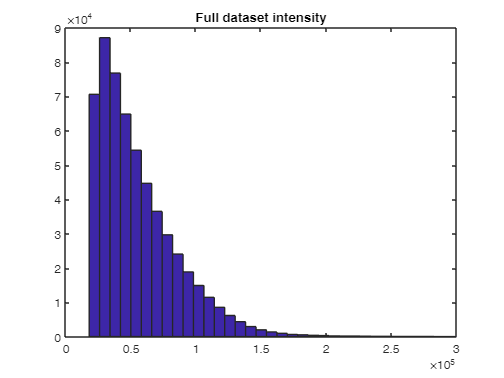

%First we download and load  data...
data_vimentin = commonFunctions.readTXTRapidSTORM('vimentin_BC2.txt');
%The intensity in this dataset is in the fourth (last) column

%Now we can show a histogram of the intensities
figure();
hist(data_vimentin(:,4), 50);
title('Full dataset intensity');
axis([0, 300000, 0, 90000]);

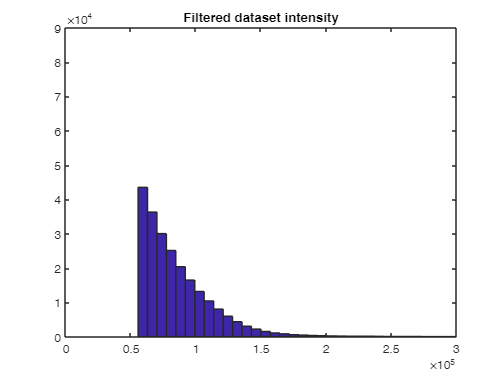


% Maybe we only want to look at the intensities that have a higher value than 
%  the mean of all intensities
%  We can select these datapoints like this:
% Note that what we do here, is that instead of selecting all columns in the 
% dataset - indicated by ':' above, we only select the columns that satisfy the
% condition 'data_vimentin[:,3]>np.mean(data_vimentin[:,3])'.
data_vimentin_filtered = data_vimentin(data_vimentin(:,4)>mean(data_vimentin(:,4)),:);

% Be aware that you can always look at the Workspace in the right-hand-side
% to investigate the variables and data
% 
% Now we can show a histogram of the intensities
figure();
hist(data_vimentin_filtered(:,4), 50);
title('Filtered dataset intensity')
axis([0, 300000, 0, 90000]);


%We note that this is a much smaller list of datapoints:
disp('Size original array:')

Size original array:


disp(size(data_vimentin))

      563041           4



disp('Size itensity-filtered array:')

Size itensity-filtered array:


disp(size(data_vimentin_filtered))

      225069           4



## ROI selection

Often only a specific region-of-interest (ROI) needs to be selected, after which post-processing needs to be done. Here we explain how to perform this ROI selection. This is very similar to filtering on intensity as shown above

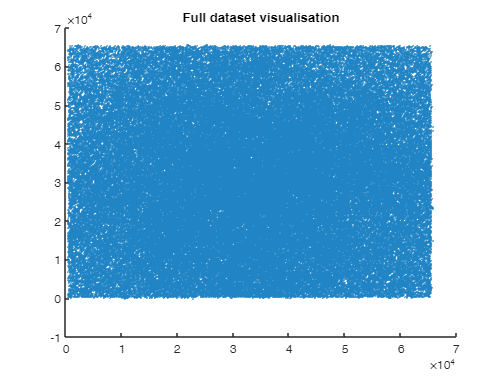

data_Nanorulers = commonFunctions.readCSVThunderSTORM('Data/ChromAbb_greenPoints_light.csv');

%Next, we visualise all of this data via a scatter plot
figure()
scatter(data_Nanorulers(:,2),data_Nanorulers(:,3), 1)
title('Full dataset visualisation');

%We see that this is way too much data to be visualised like this. Thus, we want
%to extract a small ROI in the center and look at that
%To do this, first, we make an index list - this will be a list with 'True' or
% 'False' values, where the x-position is between 32000 and 36000, and the y-position
% is between 25000 and 29000
localizations_ROI_index = data_Nanorulers(:,2) > 32000 & data_Nanorulers(:,2) < 36000 & data_Nanorulers(:,3) > 25000 & data_Nanorulers(:,3) < 29000;

%Now we create a new matrix that only contains these datapoints
data_Nanorulers_ROI_selected = data_Nanorulers(localizations_ROI_index,:);

%We note that this is a much smaller list of datapoints:
disp('Size original array:')

Size original array:


disp(size(data_Nanorulers))

      970791           4



disp('Size ROI-filtered array:')

Size ROI-filtered array:


disp(size(data_Nanorulers_ROI_selected))

        4989           4



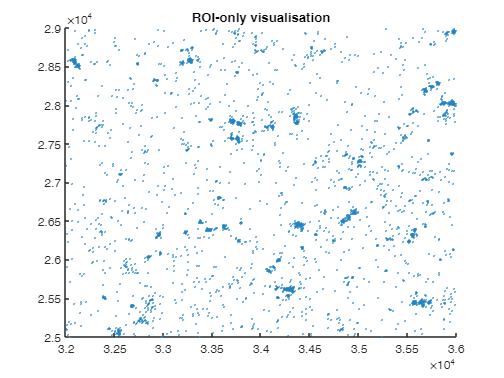


%Finally, we visualise the ROI-filtered data 
figure()
scatter(data_Nanorulers_ROI_selected(:,2),data_Nanorulers_ROI_selected(:,3), 1)
title('ROI-only visualisation');

## Change localization units

In the nanoruler data (shown above), the localizations are present as nanometer-values. Sometimes it's usefull to have these as pixel values. Here we explain how to make this change.

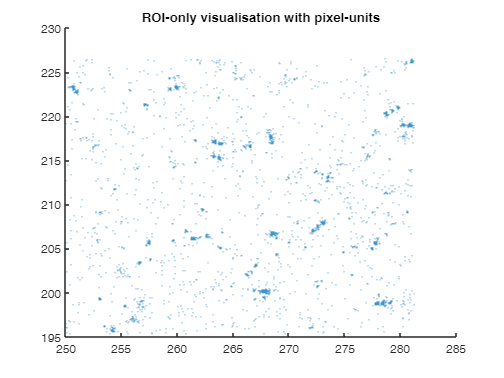

%First, we make a copy of the matrix to not overwrite the old matrix
data_Nanorulers_ROI_selected_pixel = data_Nanorulers_ROI_selected;

%Next, we change columns 2 and 3 (x,y position) from nm to pixels
pixel_size = 128; %Our microscope has 128 nm/pixel size

%We simply divide the values in column 2 and 3 by the pixel size like this:
data_Nanorulers_ROI_selected_pixel(:,[2:3]) = data_Nanorulers_ROI_selected_pixel(:,[2:3])/pixel_size;

%If we now visualise this, we can observe the effect:
figure()
scatter(data_Nanorulers_ROI_selected_pixel(:,2),data_Nanorulers_ROI_selected_pixel(:,3), 0.2);
title('ROI-only visualisation with pixel-units');

## Add a column in an array and basic matrix arithmatic

In the Vimentin dataset, the intensity values are stored as EMCCD counts, while they might provide more insight as photons. Here we show how to add a column to an array and do basic arithmatic on a specific data column

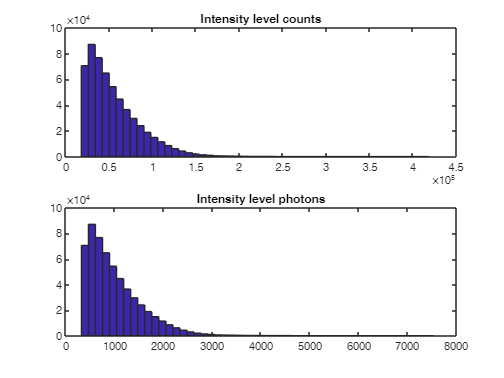

data_vimentin = commonFunctions.readTXTRapidSTORM('vimentin_BC2.txt');
% The intensity data is stored in the last column of data_vimentin.
% First, we add an extra column to the data
% To do this, we create a zeros-column of the correct size
zeros_column = zeros(size(data_vimentin,1),1);
%And we add this column to the right end:
data_vimentin = [data_vimentin, zeros_column];

%Next, we provide the values for this column, based on the fourth column, which
%contains the intensity value in counts
data_vimentin(:,5) = data_vimentin(:,4)-138; %Subtract offset from the counts-column
data_vimentin(:,5) = data_vimentin(:,5)*5.4; %Multiply every value in the photon-column with the pre-amp
data_vimentin(:,5) = data_vimentin(:,5)/300; %Divide every value in the photon-column with the EM Gain

figure()
subplot(2,1,1)
hist(data_vimentin(:,4), 50)
title('Intensity level counts');
subplot(2,1,2)
hist(data_vimentin(:,5), 50)
title('Intensity level photons');